# Boston Navi App

## INIT

clc;
clear all;
close all;
format long
boston_roads = shaperead('boston_roads.shp');
%init_shapefile()
%[worldfile, shapefile] = calcWorldFile();

## Matfiles laden

Highways = load('Highways');
All = load('All');
Local = load('Local');


##  P1 Strassen darstellen

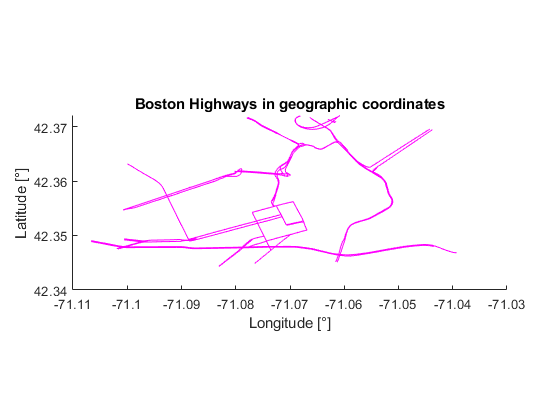

figure
mapshow(Highways.lon,Highways.lat, 'Color','m')
title('Boston Highways in geographic coordinates')
xlabel('Longitude [°]')
ylabel('Latitude [°]')

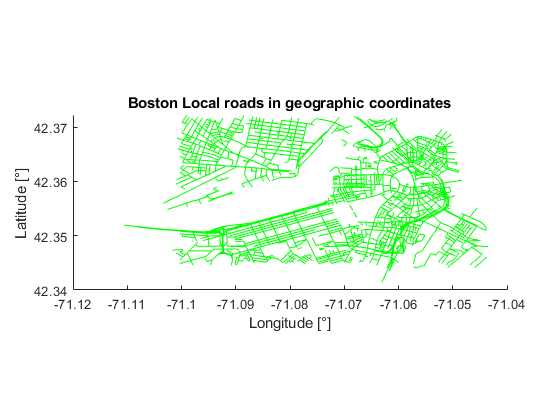

figure
mapshow(Local.lon,Local.lat, 'Color','g')
title('Boston Local roads in geographic coordinates')
xlabel('Longitude [°]')
ylabel('Latitude [°]')

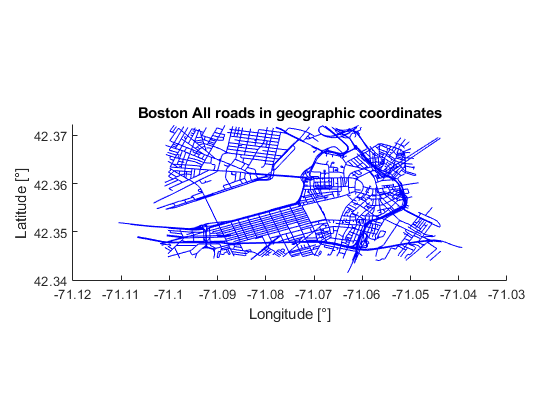

figure
mapshow(All.lon,All.lat, 'Color','b')
title('Boston All roads in geographic coordinates')
xlabel('Longitude [°]')
ylabel('Latitude [°]')

## P2 Karten georeferenzieren

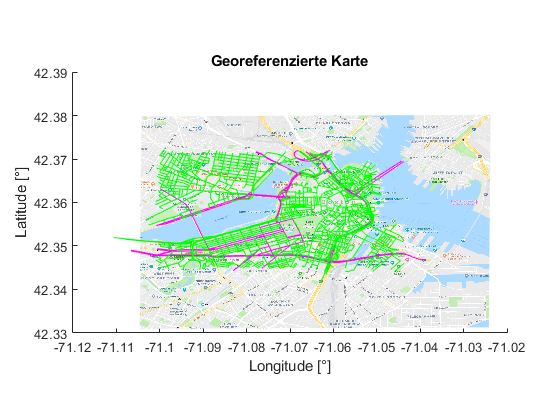

figure
mapshow('worldfile.PNG')
%hold on
%mapshow('roads_geo_out.shp')
hold on
mapshow(Highways.lon,Highways.lat, 'Color','m')
hold on
mapshow(Local.lon,Local.lat, 'Color','g')
title('Georeferenzierte Karte')
xlabel('Longitude [°]')
ylabel('Latitude [°]')

## Punkte durch User input einlesen

% Startpunkt waehlen
% min_lon = min(All.lon); min_lat = min(All.lat);
% max_lon = max(All.lon); max_lat = max(All.lat);
% disp('Bitte Startpunkt mit Laengen- und Breitengrad angeben.')
% prompt_orig = ['\nBitte Laengengrad zwischen: ', num2str(min_lon), ...
%     ' und ', num2str(max_lon), ' eingeben:\n' ];
%
% start_lon = input(prompt_orig);
% while start_lon < min_lon || start_lon > max_lon
%     prompt = [num2str(start_lon), ' ist nicht gueltig. ', prompt_orig];
%     start_lon = input(prompt);
% end
% prompt_orig = ['Bitte Breitengrad zwischen: ', num2str(min_lat), ...
%     ' und ', num2str(max_lat), ' eingeben:\n' ];
% start_lat = input(prompt_orig);
% while start_lat < min_lat || start_lat > max_lat
%     prompt = [num2str(start_lat), ' ist nicht gueltig. ', prompt_orig];
%     start_lat = input(prompt);
% end
% disp(['Startpunkt gewaehlt: ', num2str(start_lon), ', ', num2str(start_lat)]);

% Endpunkt waehlen
% min_lon = min(All.lon); min_lat = min(All.lat);
% max_lon = max(All.lon); max_lat = max(All.lat);
% disp('Bitte Endpunkt mit Laengen- und Breitengrad angeben.')
% prompt_orig = ['\nBitte Laengengrad zwischen: ', num2str(min_lon), ...
%     ' und ', num2str(max_lon), ' eingeben:\n' ];
%
% end_lon = input(prompt_orig);
% while end_lon < min_lon || end_lon > max_lon
%     prompt = [num2str(end_lon), ' ist nicht gueltig. ', prompt_orig];
%     end_lon = input(prompt);
% end
% prompt_orig = ['Bitte Breitengrad zwischen: ', num2str(min_lat), ...
%     ' und ', num2str(max_lat), ' eingeben:\n' ];
% end_lat = input(prompt_orig);
% while end_lat < min_lat || end_lat > max_lat
%     prompt = [num2str(end_lat), ' ist nicht gueltig. ', prompt_orig];
%     end_lat = input(prompt);
% end
% disp(['Endpunktpunkt gewaehlt: ', num2str(start_lon), ', ', num2str(start_lat)]);

## P2 Eingegebene Koordinaten in NAD83 Koordinaten transformieren

% proj = geotiffinfo('boston.tif');
% [x_start,y_start] = projfwd(proj,start_lat, start_lon)
% [x_end, y_end] = projfwd(proj, end_lat, end_lon)


## P3 Adjazensmatrix

% Alle Shapefile Koordinaten in eine Liste der Form L = (start1,start2,....startn,end1,end2,....endn) schreiben
clc
N = length(boston_roads);
for i = 1 : N
    x = boston_roads(i).X;
    y = boston_roads(i).Y;
      
    x(isnan(x)) = [];
    y(isnan(y)) = [];
    x_t(1,1) = x(1,1);
    x_t(1,2) = x(1,(length(x)));
    y_t(1,1) = y(1,1);
    y_t(1,2) = y(1,(length(y)));
    
    % L Vektor erstellen
    L(i,1) = x_t(1,1); % Start x
    L(i,2) = y_t(1,1); % Start y
    L(N+i,1) = x_t(1,2); % End x
    L(N+i,2) = y_t(1,2); % End y

end

% Kreuzungen entdecken und in Adjazezmatrix schreiben
tic
A = zeros(N*2,N*2);
min_dist = min([boston_roads.LENGTH])

min_dist =    2.251085000000000


index = 1;
% min_dist = min(min_dist)
for i = 1 : N*2
    P1 = L(i,:); 
    for k = 1 : N*2
        P2 = L(k,:);
        % Strecke zwischen zwei Punkten berechnen
        s = sqrt((P1(1,1) - P2(1,1))^2 + (P1(1,2) - P2(1,2))^2);
        if s < min_dist*5 && s > 0
            % Kreuzung gefunden
            A(i,k) = 2;
            A(k,i) = 2;
            Kreuzungen(index,1:2) = P1;
            Kreuzungen(index,3:4) = P2;
            index = index + 1;
        end
    end
end
% Adjazenzmatrix mit 1ern befüllen zwischen start und ende
% A = zeros(N*2,N*2);
for i = 1 : N
    A(i,i+N) = 1;
    A(i+N,i) = 1; 
end




## Visualisierung

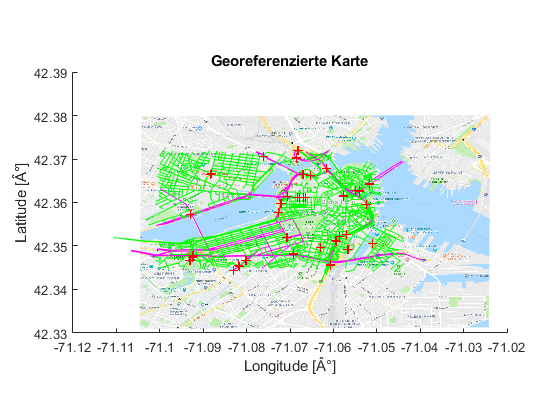

boston_tif = geotiffread('boston.tif');
proj = geotiffinfo('boston.tif');
mstruct = geotiff2mstruct(proj);
x_1 = [Kreuzungen(:,1)] * unitsratio('survey feet', 'meter');
y_1 = [Kreuzungen(:,2)] * unitsratio('survey feet', 'meter');
% X und Y Koordinaten in Laengen- und Breitengrad umrechnen und darstellen
[lat_1,lon_1] = projinv(proj,x_1,y_1);
x_2 = [Kreuzungen(:,3)] * unitsratio('survey feet', 'meter');
y_2 = [Kreuzungen(:,4)] * unitsratio('survey feet', 'meter');
% X und Y Koordinaten in Laengen- und Breitengrad umrechnen und darstellen
[lat_2,lon_2] = projinv(proj,x_2,y_2);
% save('Kreuzungen_lat_lon', 'lat_1', 'lon_1', 'lat_2', 'lon_2');
%%P2 Karten georeferenzieren
figure
mapshow('worldfile.PNG')
hold on
mapshow(Highways.lon,Highways.lat, 'Color','m')
hold on
mapshow(Local.lon,Local.lat, 'Color','g')
hold on
geoshow(lat_1, lon_1, 'Color', 'r', 'DisplayType', 'point')
hold on
geoshow(lat_2, lon_2, 'Color', 'r', 'DisplayType', 'point')
title('Georeferenzierte Karte')
xlabel('Longitude [Â°]')
ylabel('Latitude [Â°]')

toc

Elapsed time is 157.652134 seconds.


## Test shapefiletoadjmatrix

test_mat = shapefileToAdjMatrix('all');





